#### 论文版本 - 正确版本

plant_num  = -0.5125 * [1 0 45.915];
plant_denum = [1 0 -36.225 0 0];
P = tf(plant_num, plant_denum);

numC2 = [-1520, -1.439e4, -4.623e4, -1.237e5];
denC2 = [1, 40.65, 2.664, 2089];
essay_C2 = tf(numC2, denC2)


essay_C2 =
 
  -1520 s^3 - 14390 s^2 - 46230 s - 123700
  ----------------------------------------
      s^3 + 40.65 s^2 + 2.664 s + 2089
 
Continuous-time transfer function.
Model Properties


L  = minreal(P*essay_C2);
S  = feedback(1, L)


S =
 
               s^7 + 40.65 s^6 - 33.56 s^5 + 616.5 s^4 - 96.5 s^3 - 7.567e04 s^2
  --------------------------------------------------------------------------------------------
  s^7 + 40.65 s^6 + 745.4 s^5 + 7991 s^4 + 5.936e04 s^3 + 3.263e05 s^2 + 1.088e06 s + 2.911e06
 
Continuous-time transfer function.
Model Properties



numC1 = [-188, -1131.76, -15331.87, -41602.88, -248066.96];
denC1 = [1, 42.64, 83.6782, 2094.9412, 4180.2895];
essay_C1 = tf(numC1, denC1)


essay_C1 =
 
  -188 s^4 - 1132 s^3 - 1.533e04 s^2 - 4.16e04 s - 2.481e05
  ---------------------------------------------------------
         s^4 + 42.64 s^3 + 83.68 s^2 + 2095 s + 4180
 
Continuous-time transfer function.
Model Properties



T = minreal((P*essay_C1)/(1 + P*essay_C2))


T =
 
               96.35 s^9 + 4497 s^8 + 3.612e04 s^7 + 7.5e05 s^6 + 3.682e06 s^5 + 4.66e07 s^4 + 1.471e08 s^3 + 1.259e09 s^2 + 2.061e09 s + 1.219e10
  -------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 83.29 s^10 + 2562 s^9 + 4.527e04 s^8 + 5.518e05 s^7 + 5.258e06 s^6 + 3.983e07 s^5 + 2.344e08 s^4 + 1.147e09 s^3 + 3.887e09 s^2 + 1.065e10 s + 1.217e10
 
Continuous-time transfer function.


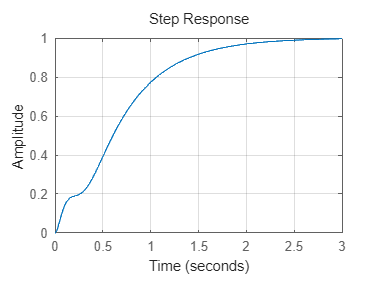

step(T); grid on;

Debug 我们这里的C2